clear
syms r t u p xx r1 r2 r3 r4 t1 t2 t3 t4 u1 u2 u3 u4 p1 p2 p3 p4 l2 l3
x(1)=0;
x(2)=40;
x(3)=50;
x(4)=60;
x(5)=100;
y(1)=0.0;
%max=120%(x4-x2)
y(3)=(1/(x(4)-x(2))*1.2);
%y(3)=;
%+90*0.00012;
y(2)=(y(3)+1/(x(5)-x(1)))/2

y =          0    0.0350    0.0600


y(4)=y(2);
y(5)=0.0;
step=0.1;
k=1;
x=x+1;
a(xx)=r1*xx^3+t1*xx^2+u1*xx+p1;
s1(xx)=t2*xx^2+u2*xx+p2;
s2(xx)=t3*xx^2+u3*xx+p3;
d(xx)=r4*xx^3+t4*xx^2+u4*xx+p4;
F=[a(xx) s1(xx) s2(xx) d(xx) ];

aa(xx)=diff(a(xx));
ss1(xx)=diff(s1(xx));
ss2(xx)=diff(s2(xx));
dd(xx)=diff(d(xx));
FF=[aa(xx) ss1(xx) ss2(xx) dd(xx) ];

for i=2:3
    D(xx)=F(i);
    E(k)=D(x(i))==y(i);
    k=k+1;
    E(k)=D(x(i+1))==y(i+1);
    k=k+1;
end
[u2, p2]=solve([E(1) E(2)], [u2 p2]);
[u3, p3]=solve([E(3) E(4)], [u3 p3]);
FF=eval(FF);
D(xx)=FF(2);
DD(xx)=FF(3);
EE(1)=D(x(3))==0;
EE(2)=DD(x(3))==0;
t2=solve([EE(1)],t2);
t3=solve([EE(2)],t3);
eval(EE);
s1(xx)=eval(s1(xx));
s1(xx)=eval(s1(xx));
s1(xx)=eval(s1(xx));
s2(xx)=eval(s2(xx));
s2(xx)=eval(s2(xx));
s2(xx)=eval(s2(xx));
s1(xx)=eval(s1(xx));
s2(xx)=eval(s2(xx));
aa(xx)=diff(a(xx));
ss1(xx)=diff(s1(xx));
ss2(xx)=diff(s2(xx));
dd(xx)=diff(d(xx));
FF=[aa(xx) ss1(xx) ss2(xx) dd(xx) ];
aaa(xx)=diff(aa(xx))

$$aaa(xx) = 6\,{r_{1}}^{2}\,t_{1}\,\delta (r_{1}\,\mathrm{xx})\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2}+6\,{r_{1}}^{2}\,t_{1}\,{\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)}^{2}\,\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)$$

sss1(xx)=diff(ss1(xx))

$$sss1(xx) = -\frac{1}{2000}$$

sss2(xx)=diff(ss2(xx))

$$sss2(xx) = -\frac{1}{2000}$$

ddd(xx)=diff(dd(xx))

$$ddd(xx) = 6\,{r_{1}}^{2}\,t_{4}\,\delta (r_{1}\,\mathrm{xx})\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2}+6\,{r_{1}}^{2}\,t_{4}\,{\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)}^{2}\,\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)$$

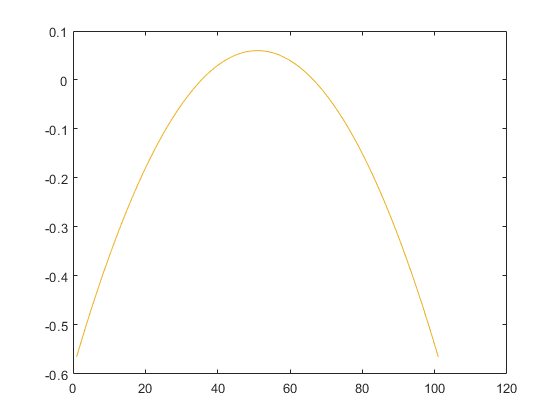

FFF=[aaa(xx) sss1(xx) sss2(xx) ddd(xx) ];
x1=(x(1):step:x(2));
x2=(x(2):step:x(3));
x3=(x(3):step:x(4));
x4=(x(4):step:x(5));
XA=(x(1):step:x(5));
X=[x1 x2 x3 x4];
Y=[s1(x1) s1(x2) s2(x3) s2(x4)];
plot(XA, s1(XA), XA, s2(XA), X, Y)

%plot(XA, ss1(XA), XA, ss2(XA))
g=1-(int(s1(xx),x(2),x(3))+int(s2(xx),x(3),x(4)))

$$g = -\frac{1}{30}$$

double(g)

ans = -0.0333


clear E
k=1

k = 1

D(xx)=F(1);
E(k)=D(x(1))==y(1);
k=k+1;
E(k)=D(x(2))==y(2);
k=k+1;
D(xx)=F(4);
E(k)=D(x(4))==y(4);
k=k+1;
E(k)=D(x(5))==y(5);
k=k+1;
E

$$E = \left(\begin{array}{cccc} p_{1}+t_{1}\,{\left(u_{1}+\left|r_{1}\right|\right)}^{3}=0 & p_{1}+t_{1}\,{\left(u_{1}+41\,\left|r_{1}\right|\right)}^{3}=\frac{7}{200} & p_{4}+t_{4}\,{\left(u_{1}+61\,\left|r_{1}\right|\right)}^{3}=\frac{7}{200} & p_{4}+t_{4}\,{\left(u_{1}+101\,\left|r_{1}\right|\right)}^{3}=0 \end{array}\right)$$

[t1, p1]=solve([E(1) E(2)], [t1 p1])

$$t1 = \frac{7}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)}$$

$$p1 = -\frac{7\,{\left(u_{1}+\left|r_{1}\right|\right)}^{3}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)}$$

[t4, p4]=solve([E(3) E(4)], [t4 p4])

$$t4 = -\frac{7}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+486\,u_{1}\,{\left|r_{1}\right|}^{2}+20083\,{\left|r_{1}\right|}^{3}\right)}$$

$$p4 = \frac{7\,{\left(u_{1}+101\,\left|r_{1}\right|\right)}^{3}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+486\,u_{1}\,{\left|r_{1}\right|}^{2}+20083\,{\left|r_{1}\right|}^{3}\right)}$$


FF=eval (FF)

$$FF = \begin{array}{l} \left(\begin{array}{cccc} \frac{\sigma_{1}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)} & \frac{51}{2000}-\frac{\mathrm{xx}}{2000} & \frac{51}{2000}-\frac{\mathrm{xx}}{2000} & -\frac{\sigma_{1}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+486\,u_{1}\,{\left|r_{1}\right|}^{2}+20083\,{\left|r_{1}\right|}^{3}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=21\,r_{1}\,\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2} \end{array}$$

clear E H
G(xx)=FF(1)

$$G(xx) = \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)}$$

D(xx)=FF(2)

$$D(xx) = \frac{51}{2000}-\frac{\mathrm{xx}}{2000}$$

DD(xx)=FF(3)

$$DD(xx) = \frac{51}{2000}-\frac{\mathrm{xx}}{2000}$$

H(xx)=FF(4)

$$H(xx) = -\frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+486\,u_{1}\,{\left|r_{1}\right|}^{2}+20083\,{\left|r_{1}\right|}^{3}\right)}$$


E(1)=G(x(2))==D(x(2))

$$E = \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+41\,\left|r_{1}\right|\right)}^{2}}{8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)}=\frac{1}{200}$$

E(2)=G(x(1))==0

$$E = \begin{array}{l} \left(\begin{array}{cc} \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+41\,\left|r_{1}\right|\right)}^{2}}{\sigma_{1}}=\frac{1}{200} & \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+\left|r_{1}\right|\right)}^{2}}{\sigma_{1}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8000\,\left(3\,{u_{1}}^{2}\,\left|r_{1}\right|+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right) \end{array}$$

E(3)=H(x(4))==DD(x(4))

$$E = \begin{array}{l} \left(\begin{array}{ccc} \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+41\,\left|r_{1}\right|\right)}^{2}}{\sigma_{1}}=\frac{1}{200} & \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+\left|r_{1}\right|\right)}^{2}}{\sigma_{1}}=0 & -\frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+61\,\left|r_{1}\right|\right)}^{2}}{8000\,\left(\sigma_{2}+486\,u_{1}\,{\left|r_{1}\right|}^{2}+20083\,{\left|r_{1}\right|}^{3}\right)}=-\frac{1}{200} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8000\,\left(\sigma_{2}+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)\\ \sigma_{2}=3\,{u_{1}}^{2}\,\left|r_{1}\right| \end{array}$$

E(4)=H(x(5))==0

$$E = \begin{array}{l} \left(\begin{array}{cccc} \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+41\,\left|r_{1}\right|\right)}^{2}}{\sigma_{2}}=\frac{1}{200} & \frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+\left|r_{1}\right|\right)}^{2}}{\sigma_{2}}=0 & -\frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+61\,\left|r_{1}\right|\right)}^{2}}{\sigma_{1}}=-\frac{1}{200} & -\frac{21\,r_{1}\,\mathrm{sign}\left(r_{1}\right)\,{\left(u_{1}+101\,\left|r_{1}\right|\right)}^{2}}{\sigma_{1}}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8000\,\left(\sigma_{3}+486\,u_{1}\,{\left|r_{1}\right|}^{2}+20083\,{\left|r_{1}\right|}^{3}\right)\\ \sigma_{2}=8000\,\left(\sigma_{3}+126\,u_{1}\,{\left|r_{1}\right|}^{2}+1723\,{\left|r_{1}\right|}^{3}\right)\\ \sigma_{3}=3\,{u_{1}}^{2}\,\left|r_{1}\right| \end{array}$$


[u1, r1]=solve([E(1) E(2)], [u1 r1])
[u4, r4]=solve([E(3) E(4)], [u4 r4])


 
u1 =
 
Empty sym: 0-by-1
 
 
r1 =
 
Empty sym: 0-by-1
 


 
u4 =
 
Empty sym: 0-by-1
 
 
r4 =
 
Empty sym: 0-by-1
 


G(xx)=FFF(1)

$$G(xx) = 6\,{r_{1}}^{2}\,t_{1}\,\delta (r_{1}\,\mathrm{xx})\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2}+6\,{r_{1}}^{2}\,t_{1}\,{\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)}^{2}\,\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)$$

D(xx)=FFF(2)

$$D(xx) = -\frac{1}{2000}$$

DD(xx)=FFF(3)

$$DD(xx) = -\frac{1}{2000}$$

H(xx)=FFF(4)

$$H(xx) = 6\,{r_{1}}^{2}\,t_{4}\,\delta (r_{1}\,\mathrm{xx})\,{\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)}^{2}+6\,{r_{1}}^{2}\,t_{4}\,{\mathrm{sign}\left(r_{1}\,\mathrm{xx}\right)}^{2}\,\left(u_{1}+\left|r_{1}\,\mathrm{xx}\right|\right)$$


a(xx)=eval(eval(eval(eval(eval (a(xx))))))

Error using eval
Must be a string scalar or character vector.

d(xx)=eval(eval(eval(eval(eval (d(xx))))))
Y=[a(x1) s1(x2) s2(x3) d(x4)];
plot(XA, s1(XA), XA, s2(XA), XA, a(XA), XA, d(XA))
plot(X-1, Y)
w=int(a(xx),x(1),x(2))+int(s1(xx),x(2),x(3))+int(s2(xx),x(3),x(4))+int(d(xx),x(4),x(5))
double(w)